pen = 'P13';
%Give the correct directory with Kilosorted files
data_root = ['//media/alex/4TB SSD/DATA/Ronnie_23_01_2018/bin_files/Preprocessed/CRA_done/',pen,'-reverb_with_noise_same_cra/',pen,'-reverb_with_noise_same_cra_sorted'];
%Give the correct Benware Grid folder
grid_root = ['/media/alex/4TB SSD/DATA/Ronnie_23_01_2018/benware_gridinfo/',pen,'-reverb_with_noise_same'];
sound_files_root = '/media/alex/4TB SSD/DATA/Ronnie_23_01_2018/reverb_with_noise_stimuli/wav_files/reverb_with_noise_same';
sahani_path = ['/media/alex/4TB SSD/DATA/Ronnie_23_01_2018/metadata/',pen,'-reverb_with_noise_same_psth_sahani'];
synch_path = ['/media/alex/4TB SSD/DATA/Ronnie_23_01_2018/metadata/synch_ch_reverbwithnoisesame_',pen];


NPSP_val = 40; %The NPSP val that is used fir thresholding the 'good clusters'
time_bin_ms = 10; %The size of the time bin for the cochleagram and psth in ms
n_h = 30; %The number of history steps for the STRF

min_trig_length_s = 20; %The minmum trigger length in seconds. This will depend on the stimulus. It is best practice to check the synch channel always
fs = 30000; %Sampling rate in seconds
qualityOpt = 'nonoise'; %Which untis you want to analyse
%% Generate the cochleagram
[coch,t_s] = cochleagram_alex(sound_files_root,time_bin_ms,n_h);

%% Get the synch channel
load(synch_path);
%% Get the triggers
if strcmp(pen,'P06')
    [start_time_ms] = get_triggers2(synch_ch,min_trig_length_s,fs);
else
    [start_time_ms] = get_triggers(synch_ch,min_trig_length_s,fs);
end
%% Get the spike times
Y = get_spike_times(data_root,qualityOpt);
%% Load the psth_sahani and sort clusters
load(sahani_path);
count = 0;
for cluster_no = 1:numel(psth_sahani)
    if psth_sahani(cluster_no).NPSP < NPSP_val
        count = count + 1;
        good_clusters(count,1) = psth_sahani(cluster_no).cluster_id;
        good_clusters(count,2) = psth_sahani(cluster_no).NPSP;
    end
end
good_clusters = sortrows(good_clusters,2);
good_cluster_id = good_clusters(:,1);
no_good_clusters = numel(good_cluster_id);
%% Generate the PSTHs
n_h = coch(1).params.n_h;
psth_all = get_psth_strf(Y,start_time_ms,t_s,grid_root,good_cluster_id,n_h);

== Generating PSTHs ==
== Processing cluster 1/45 ==
== Processing cluster 2/45 ==
== Processing cluster 3/45 ==
== Processing cluster 4/45 ==
== Processing cluster 5/45 ==
== Processing cluster 6/45 ==
== Processing cluster 8/45 ==
== Processing cluster 10/45 ==
== Processing cluster 12/45 ==
== Processing cluster 14/45 ==
== Processing cluster 16/45 ==
== Processing cluster 18/45 ==
== Processing cluster 20/45 ==
== Processing cluster 22/45 ==
== Processing cluster 24/45 ==
== Processing cluster 26/45 ==
== Processing cluster 27/45 ==
== Processing cluster 28/45 ==
== Processing cluster 29/45 ==
== Processing cluster 30/45 ==
== Processing cluster 34/45 ==
== Processing cluster 9/45 ==
== Processing cluster 33/45 ==
== Processing cluster 13/45 ==
== Processing cluster 35/45 ==
== Processing cluster 25/45 ==
== Processing cluster 17/45 ==
== Processing cluster 31/45 ==
== Processing cluster 19/45 ==
== Processing cluster 11/45 ==
== Processing cluster 23/45 ==
== Processing cluster 32


for clust = 1:length(psth_all)
    psth_all(clust).NPSP = good_clusters(clust,2);
end

NPSP = reach(psth_all,'NPSP');
c = NPSP;
sz = 70;

anech_psth = reach(psth_all,'anech').*(1000/time_bin_ms);
anech_psth = reshape(anech_psth,numel(psth_all(1).anech),no_good_clusters);
anech_psth = anech_psth';
l_per_reverbcond = size(anech_psth,2);
l_per_indcond = l_per_reverbcond;

reverb1_psth = reach(psth_all,'reverb1').*(1000/time_bin_ms);
reverb1_psth = reshape(reverb1_psth,numel(psth_all(1).reverb1),no_good_clusters);
reverb1_psth = reverb1_psth';

reverb2_psth = reach(psth_all,'reverb2').*(1000/time_bin_ms);
reverb2_psth = reshape(reverb2_psth,numel(psth_all(1).reverb2),no_good_clusters);
reverb2_psth = reverb2_psth';


Perform PCA on the covariance matrix of neuronal firing rates

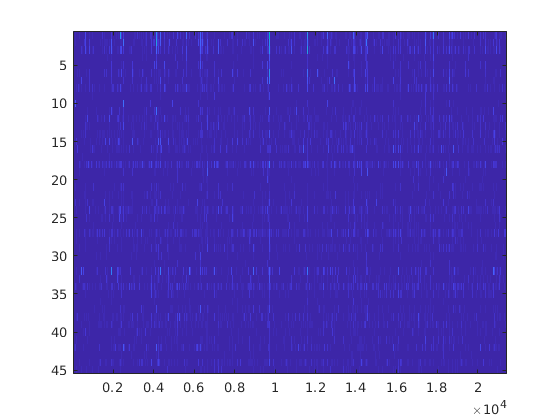

X_nt = [anech_psth,reverb1_psth,reverb2_psth];
figure;
imagesc(X_nt);

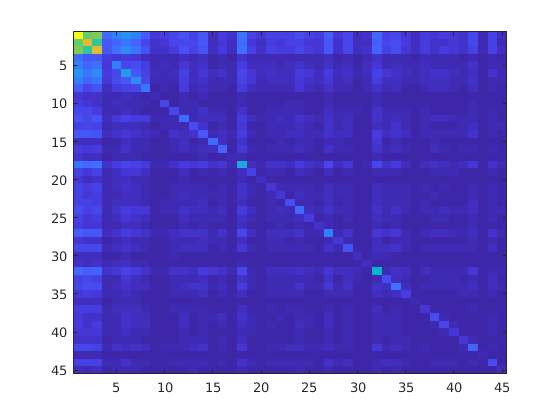

mean_X_n = mean(X_nt,2);
norm_X_nt = X_nt - mean_X_n;
figure;
C = cov(norm_X_nt');
figure;
imagesc(C);

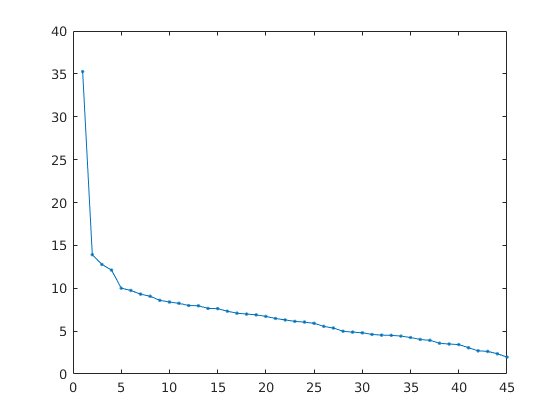

[U,D] = eig(C);
U = fliplr(U);
lambda = diag(D);
lambda = flipud(lambda);
var_total = sum(lambda);
norm_lambda = lambda/var_total;
cum_lambda = cumsum(norm_lambda);
sqrt_lambda = sqrt(lambda);
figure;
plot(sqrt_lambda,'.-');

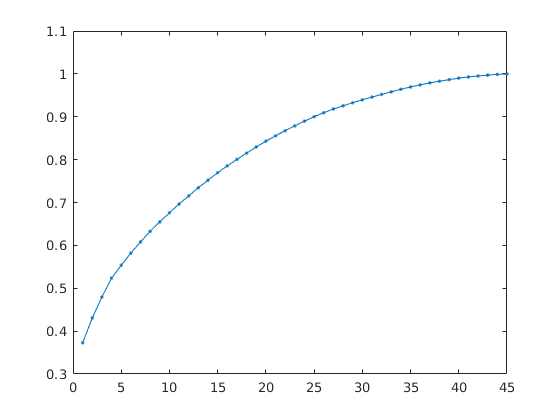

figure;
plot(cum_lambda,'.-');

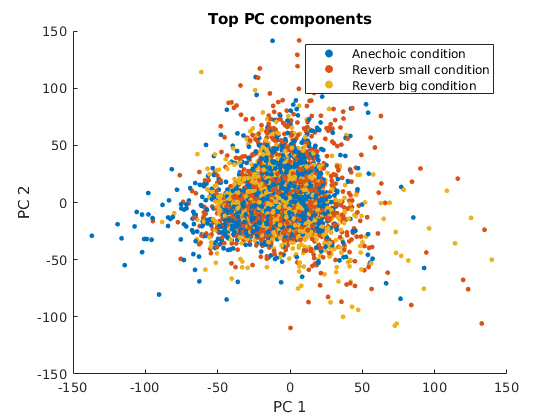


first_PCcomp = 2;
last_PCcomp = 4;
T = size(X_nt,2);
D = size(X_nt,1);
Z = U(:,first_PCcomp:last_PCcomp)'*norm_X_nt;
cond_ix = 1:l_per_indcond:T;
figure;
hold on;
for ii = 1:numel(cond_ix)
    scatter3(Z(1,cond_ix(ii):cond_ix(ii)+l_per_indcond-1),Z(2,cond_ix(ii):cond_ix(ii)+l_per_indcond-1),Z(3,cond_ix(ii):cond_ix(ii)+l_per_indcond-1),14,'filled');
%     line(Z(1,cond_ix(ii):cond_ix(ii)+l_per_cond-1),Z(2,cond_ix(ii):cond_ix(ii)+l_per_cond-1),Z(3,cond_ix(ii):cond_ix(ii)+l_per_cond-1));
end
hold off;
title('Top PC components');
xlabel('PC 1');
ylabel('PC 2');
zlabel('PC 3');
legend('Anechoic condition','Reverb small condition','Reverb big condition');

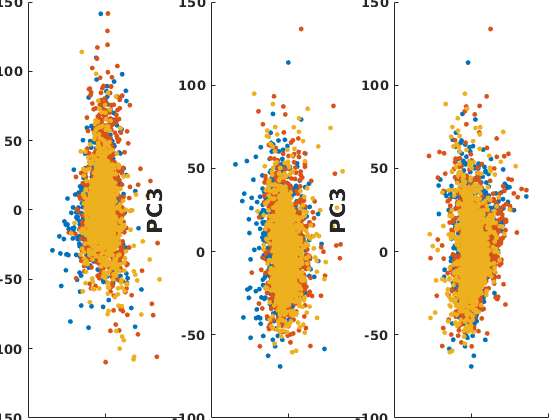


num_columns = 3;
num_rows = 1;
per = 0.005;
edgel = 0.05; edger = 0.02; edgeh = per; edgeb = per; space_h = 0.05; space_v = per;
[pos]=subplot_pos(num_rows,num_columns,edgel,edger,edgeh,edgeb,space_h,space_v);


figure;
subplot('position',pos{1});
hold on;
for ii = 1:numel(cond_ix)
    scatter(Z(1,cond_ix(ii):cond_ix(ii)+l_per_indcond-1),Z(2,cond_ix(ii):cond_ix(ii)+l_per_indcond-1),14,'filled');
end
set(gca,'FontName','Arial','FontSize',10,'FontWeight','Bold');
xlabel('PC1','FontSize',16,'FontWeight','bold');
ylabel('PC2','FontSize',16,'FontWeight','bold');
title(['PCA for components 1 & 2'],'FontSize',16,'FontWeight','bold');
hold off;


subplot('position',pos{2});
hold on;
for ii = 1:numel(cond_ix)
    scatter(Z(1,cond_ix(ii):cond_ix(ii)+l_per_indcond-1),Z(3,cond_ix(ii):cond_ix(ii)+l_per_indcond-1),14,'filled');
end
set(gca,'FontName','Arial','FontSize',10,'FontWeight','Bold');
xlabel('PC1','FontSize',16,'FontWeight','bold');
ylabel('PC3','FontSize',16,'FontWeight','bold');
title(['PCA for components 1 & 2'],'FontSize',16,'FontWeight','bold');
hold off;

subplot('position',pos{3});
hold on;
for ii = 1:numel(cond_ix)
    scatter(Z(2,cond_ix(ii):cond_ix(ii)+l_per_indcond-1),Z(3,cond_ix(ii):cond_ix(ii)+l_per_indcond-1),14,'filled');
end
set(gca,'FontName','Arial','FontSize',10,'FontWeight','Bold');
xlabel('PC2','FontSize',16,'FontWeight','bold');
ylabel('PC3','FontSize',16,'FontWeight','bold');
title(['PCA for components 1 & 2'],'FontSize',16,'FontWeight','bold');
hold off;

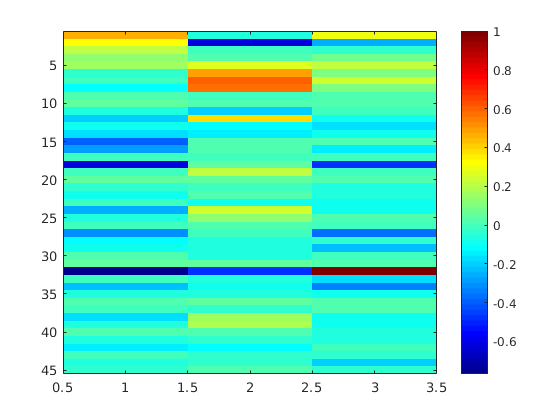


U_m = U(:,first_PCcomp:last_PCcomp);
figure;
max_U = max(U_m(:));
imagesc(U_m./max_U);
colormap(jet);
colorbar;

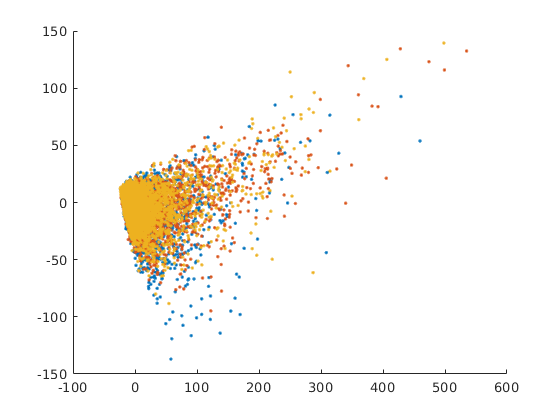


%Multidimensional scaling 

test = pdist(X_nt');
cmd_test = cmdscale(test,2);
 figure;
 hold on;
 
 for ii = 1:numel(cond_ix)
    plot(cmd_test(cond_ix(ii):cond_ix(ii)+l_per_indcond-1,1),cmd_test(cond_ix(ii):cond_ix(ii)+l_per_indcond-1,2),'.');
end